syms i theta di ai alpha off
Header = [i theta di ai alpha off]

$$Header = \left(\begin{array}{cccccc} i & \theta & \mathrm{di} & \mathrm{ai} & \alpha & \mathrm{off} \end{array}\right)$$

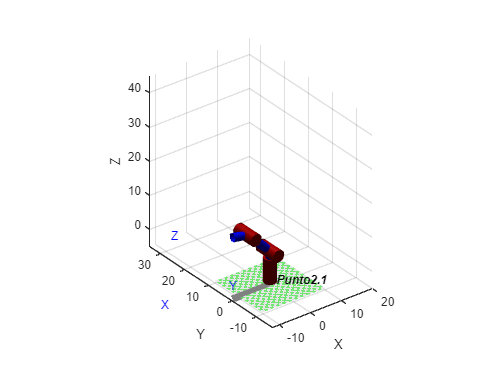


l = [0, 10.2, 10.2, 7.8];
 q = [0, 45, -55, 45]*pi/180;
 offset = [0, pi/2, pi/2, 0];
 % Orden parametros funcion link [THETA D A ALPHA SIGMA(0R,1P) OFFSET]
 DHparameters = [q(1) 5.4 l(1) pi/2 0 offset(1);
                 q(2) 0   l(2) 0    0 offset(2);
                 q(3) 0   l(3) 0    0 offset(3);
                 q(3) 0   l(4) pi/2 0 offset(4)];
 MTH(1) = Link(DHparameters(1,:));
 MTH(2) = Link(DHparameters(2,:));
 MTH(3) = Link(DHparameters(3,:));
 MTH(4) = Link(DHparameters(4,:));
 Robot_punto21 = SerialLink(MTH,'name','Punto2.1');
 ws2_2 = [-10 10 -10 10 -4.5 40];
 Robot_punto21.plot(q,'workspace',ws2_2);
 xlim([-12.0 20])
 ylim([-16.8 34.7])
 zlim([-5.0 45])